I = imread('man.tiff');
I = double(I);
T = dctmtx(8);
dct = @(block_struct) T * block_struct.data * T';
% this would pad image with zeros
B = blockproc(I,[8 8],dct);

Bq = myQ(B);

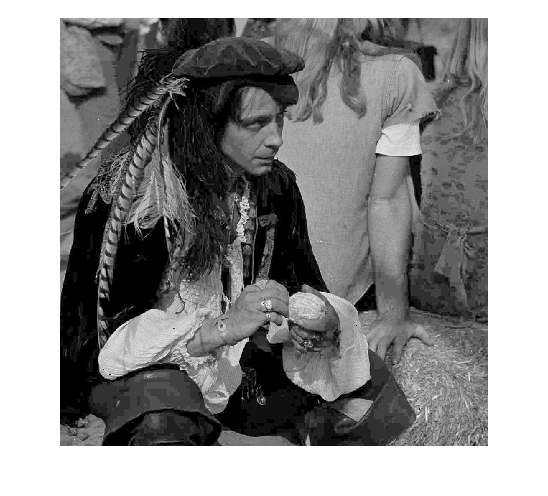

idct = @(block_struct) T' * block_struct.data * T;
Iq = blockproc(Bq,[8 8],idct);
imshow(Iq,[0 255]); truesize;